clear all

syms s tao t
global k Jl Jm Bl Bm K K1 k1 k2 k3 k4 k1_1 k2_1 k3_1 k4_1 L1 L2
k = 6; Jl= 0.5; Jm= 0.05; Bl= 0.01; Bm= 0.01;
[x1 ,x2, x3, x4]=deal(1);
ti = 0;
tfl = 300;
A=[0 1 0 0;-k/Jl -Bl/Jl k/Jl 0; 0 0 0 1; k/Jm 0 -k/Jm -Bm/Jm];
B=[0;0;0;1/Jm];
C=[1 0 0 0];
D=zeros(1);
I=eye(4);
digits(4);

E=s*I-A;%求状态转移矩阵
E_det=det(E);
H=collect(inv(E));%inv求逆，collect
E_inv=inv(E);
phit=vpa(ilaplace(collect(inv(E))));%损失精度
% phit_test=simplify(expm(A*t))

%齐次解析解
phit_real=simplify(vpa(real((ilaplace(inv(E)))),4)); %ilaplace拉普拉斯逆变换
% rewrite(phit_real,'cos')
phit_real_plot=vpa(phit_real*[x1 ;x2; x3; x4])

% [v,d]=eig(A) %V为特征向量矩阵，D为特征值矩阵

%零极点对消分析
[v,d]=eig(A); %V为特征向量矩阵，D为特征值矩阵
[z,p,kl]=ss2zp(A,B,C,D);
sys2=zpk(z,p,kl)


sys2 =
 
                  240
  -----------------------------------
  s (s+0.03636) (s^2 + 0.1836s + 132)
 
Continuous-time zero/pole/gain model.



det_E=factor(det(E));%det求行列式 factor因式分解
E_adj=adjoint(E);
E_zata=E_adj*B;
Xa=E_inv*B;
Ya=C*E_inv

$$Ya = \begin{array}{l} \left(\begin{array}{cccc} \frac{\left(50\,s+1\right)\,\left(5\,s^{2}+s+600\right)}{\sigma_{1}} & \frac{50\,\left(5\,s^{2}+s+600\right)}{\sigma_{1}} & \frac{600\,\left(5\,s+1\right)}{\sigma_{1}} & \frac{3000}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=250\,s^{4}+55\,s^{3}+33001\,s^{2}+1200\,s \end{array}$$

%状态方程中未出现零极点对消现象
Ga=C*Xa

$$Ga = \frac{60000}{250\,s^{4}+55\,s^{3}+33001\,s^{2}+1200\,s}$$

%输出方程中未出现零极点对消现象

%非齐次解析解
phit_seta_2=vpa(ilaplace(inv(E)*B*(1/s)));%
phit_final_t=simplify(vpa(real((phit*[x1; x2; x3; x4]+phit_seta_2))))

% phit_1=subs(phit,t,t-tao);%将变量t替换为t-tao
% phit_sata=int(phit_1*B,tao,0,t);%带符号类型t——10
% phit_final_t=simplify(vpa(real((phit*[x1; x2; x3; x4]+phit_sata))));
% phit_final_num=subs(phit_final_t,t,300);%将变量t替换为10

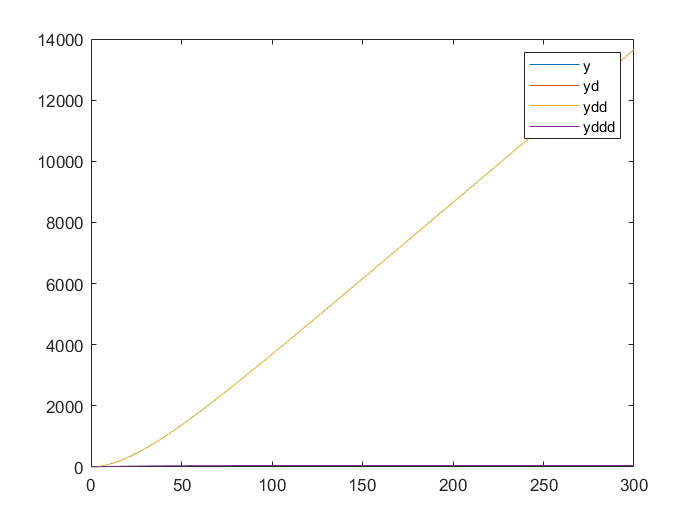

%受控项
% phit_1=subs(phit,t,t-tao);%将变量t替换为t-tao
% phit_sata=int(phit_1*B,tao,0,t);%带符号类型t——10
% phit_final_t=simplify(vpa(real((phit_sata))));

phit_seta_2=vpa(ilaplace(inv(E)*B*(1/s)));%
phit_final_t=simplify(vpa(real((phit*[x1; x2; x3; x4]+phit_seta_2))));
t=ti:0.01:tfl;
for i=1:4
   phit_plot_1=str2func(['@(t)', vectorize(phit_final_t(i))]);% 变为函数句柄
   plot(t,phit_plot_1(t))
   hold on
end
legend('y','yd','ydd','yddd')
hold off

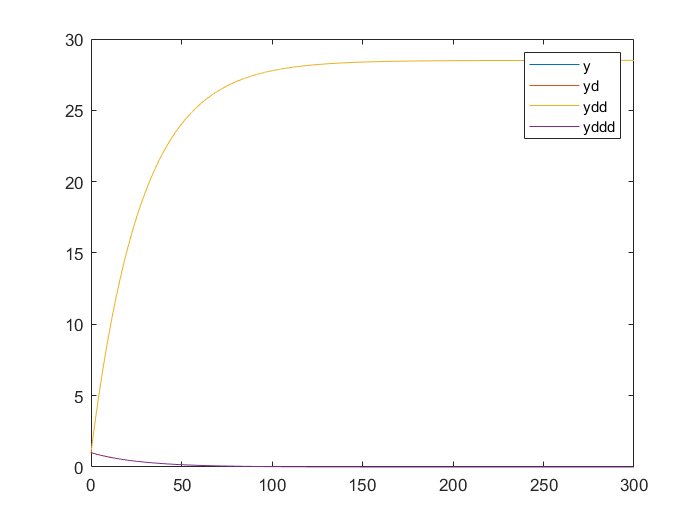

%齐次解析解绘图
%内部稳定
t=ti:0.01:tfl;
for i=1:4
   phit_plot=str2func(['@(t)', vectorize(phit_real_plot(i))]);% 变为函数句柄
   plot(t,phit_plot(t))
   hold on
end
legend('y','yd','ydd','yddd')
hold off

%非齐次解析解绘图
%输入输出稳定
t=ti:0.01:tfl;
for i=1:4
   phit_plot_1=str2func(['@(t)', vectorize(phit_final_t(i))]);% 变为函数句柄
   plot(t,phit_plot_1(t))
   hold on
end
legend('y','yd','ydd','yddd')
hold off

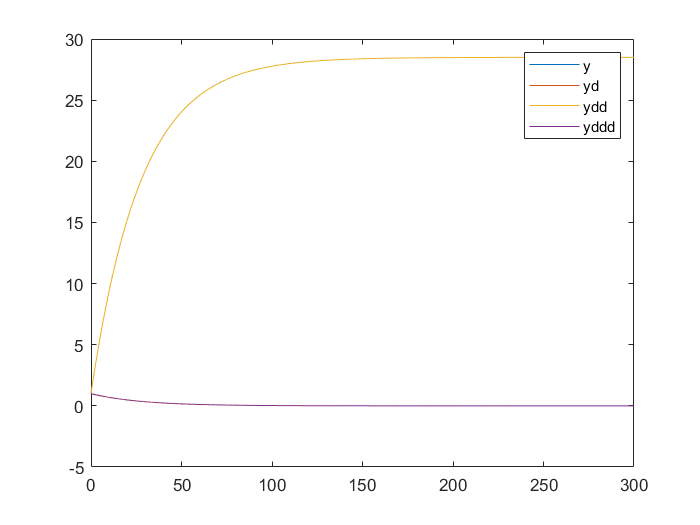

%齐次数值解
[time_lin,sol_lin]=ode45(@lin_pend_dot,[ti tfl],[x1 x2 x3 x4]);
plot(time_lin,sol_lin);
legend('y','yd','ydd','yddd');

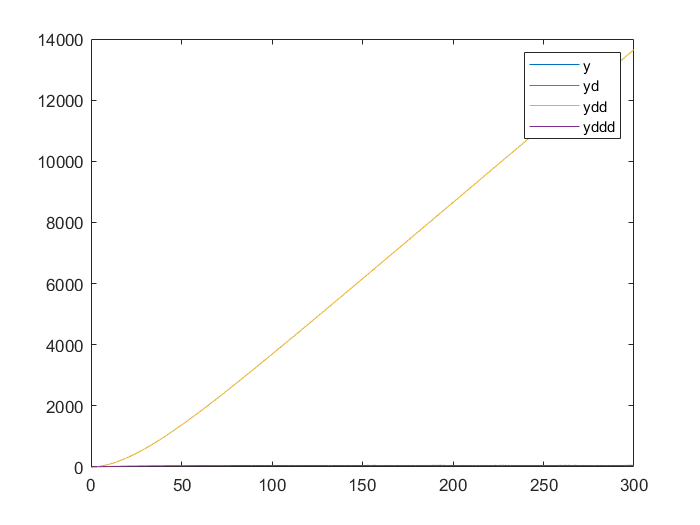

%非齐次数值解
[time_lin,sol_lin]=ode45(@lin_pend_dot1,[ti tfl],[x1 x2 x3 x4]);
plot(time_lin,sol_lin);
legend('y','yd','ydd','yddd');

%带参数判别
%能控性
Qc=[B A*B (A^2)*B (A^3)*B];
Qc_det=det(Qc) %rank(Qc)

Qc_det = 23040000

%系统能控
Qg=[C;C*A;C*A^2;C*A^3];
Qg_det=det(Qg)%rank(Qg)

Qg_det = 144

%系统能观

%无参数判别
clear all
syms k Jl Jm Bl Bm   
A=[0 1 0 0;-k/Jl -Bl/Jl k/Jl 0; 0 0 0 1; k/Jm 0 -k/Jm -Bm/Jm];
B=[0;0;0;1/Jm];
C=[1 0 0 0];
Qc=[B A*B (A^2)*B (A^3)*B];
Qc_det=det(Qc) %rank(Qc)

$$Qc\_det = \frac{k^{2}}{{\mathrm{Jl}}^{2}\,{\mathrm{Jm}}^{4}}$$

Qg=[C;C*A;C*A^2;C*A^3];
Qg_det=det(Qg)%rank(Qg)

$$Qg\_det = \frac{k^{2}}{{\mathrm{Jl}}^{2}}$$

%能控条件 K^2/((Jl^2)(Jm^4))不等于0
%能观条件 K^2/((Jl^2）不等于0

clear all
syms k Jl Jm Bl Bm   
A=[0 1 0 0;-k/Jl -Bl/Jl k/Jl 0; 0 0 0 1; k/Jm 0 -k/Jm -Bm/Jm];
B=[0;0;0;1/Jm];
C=[1 0 0 0];
%不带参数的能控标准型
Qc=[B A*B (A^2)*B (A^3)*B];
p1=[0 0 0 1]*(inv(Qc));
P=[p1;p1*A;p1*(A^2);p1*(A^3)];
A_ba_a=P*A*inv(P)

$$A\_ba\_a = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & \frac{k}{\mathrm{Jl}}-\sigma_{3}-\frac{k\,\left(\mathrm{Jm}-\frac{{\mathrm{Bl}}^{2}\,\mathrm{Jm}}{\mathrm{Jl}\,k}\right)}{\mathrm{Jl}\,\mathrm{Jm}} & 0 & 1\\ 0 & \frac{k\,\left(\frac{\mathrm{Bl}\,\mathrm{Jm}}{\mathrm{Jl}}+\frac{\mathrm{Bl}\,\mathrm{Jm}\,\left(\frac{k}{\mathrm{Jl}}-\sigma_{3}\right)}{k}\right)}{\mathrm{Jl}\,\mathrm{Jm}}-\frac{k\,\sigma_{1}}{\mathrm{Jl}\,\mathrm{Jm}}-\frac{\mathrm{Bl}\,\sigma_{2}}{\mathrm{Jl}\,\mathrm{Jm}} & -\frac{\sigma_{2}}{\mathrm{Jm}}-\frac{\mathrm{Bl}\,\sigma_{1}}{\mathrm{Jl}\,\mathrm{Jm}} & -\frac{\sigma_{1}}{\mathrm{Jm}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{Bm}+\frac{\mathrm{Bl}\,\mathrm{Jm}}{\mathrm{Jl}}\\ \sigma_{2}=k+\mathrm{Jm}\,\left(\frac{k}{\mathrm{Jl}}-\sigma_{3}\right)\\ \sigma_{3}=\frac{{\mathrm{Bl}}^{2}}{{\mathrm{Jl}}^{2}} \end{array}$$

B_ba_a=P*B

$$B\_ba\_a = \left(\begin{array}{c} 0\\ 0\\ 0\\ 1 \end{array}\right)$$

%不带参数的能观标准型
Qg=[C;C*A;C*(A^2);C*(A^3)];
T1=inv(Qg)*[0;0;0;1];
T=[T1 A*T1 (A^2)*T1 (A^3)*T1];
A_ba_b=inv(T)*A*T

$$A\_ba\_b = \begin{array}{l} \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 1 & 0 & \sigma_{1}-\frac{k}{\mathrm{Jm}}-\sigma_{3} & \frac{\mathrm{Bm}\,k}{{\mathrm{Jm}}^{2}}-\sigma_{5}-\frac{\mathrm{Jl}\,\sigma_{4}\,\left(\sigma_{1}-\sigma_{3}\right)}{k}\\ 0 & 1 & \sigma_{2}-\frac{\mathrm{Bm}}{\mathrm{Jm}}-\frac{\mathrm{Bl}}{\mathrm{Jl}} & \frac{{\mathrm{Bm}}^{2}}{{\mathrm{Jm}}^{2}}-\frac{k}{\mathrm{Jm}}-\frac{k}{\mathrm{Jl}}+\frac{\mathrm{Jl}\,\sigma_{4}\,\left(\frac{\mathrm{Bl}}{\mathrm{Jl}}-\sigma_{2}\right)}{k}\\ 0 & 0 & 1 & -\frac{\mathrm{Jl}\,\sigma_{4}}{k} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{Jl}\,k+\mathrm{Bl}\,\mathrm{Bm}}{\mathrm{Jl}\,\mathrm{Jm}}\\ \sigma_{2}=\frac{\mathrm{Bl}\,\mathrm{Jm}+\mathrm{Bm}\,\mathrm{Jl}}{\mathrm{Jl}\,\mathrm{Jm}}\\ \sigma_{3}=\frac{\mathrm{Bl}\,\mathrm{Bm}}{\mathrm{Jl}\,\mathrm{Jm}}\\ \sigma_{4}=\frac{\mathrm{Bl}\,k}{{\mathrm{Jl}}^{2}}+\sigma_{5}\\ \sigma_{5}=\frac{\mathrm{Bm}\,k}{\mathrm{Jl}\,\mathrm{Jm}} \end{array}$$

B_ba_b=inv(T)*B

$$B\_ba\_b = \left(\begin{array}{c} \frac{k}{\mathrm{Jl}\,\mathrm{Jm}}\\ 0\\ 0\\ 0 \end{array}\right)$$

C_ba_b=C*T

$$C\_ba\_b = \left(\begin{array}{cccc} 0 & 0 & 0 & 1 \end{array}\right)$$

%带参数的能控标准型
Qc=[B A*B (A^2)*B (A^3)*B];
p1=[0 0 0 1]*(inv(Qc));
P=[p1;p1*A;p1*(A^2);p1*(A^3)];
A_ba_a=P*A*inv(P)

A_ba_a =    -0.0000    1.0000   -0.0000   -0.0000
    0.0000    0.0000    1.0000    0.0000
   -0.0000   -0.0000    0.0000    1.0000
   -0.0000   -4.8000 -132.0040   -0.2200


B_ba_a=P*B

B_ba_a =      0
     0
     0
     1


%带参数的能观标准型
Qg=[C;C*A;C*(A^2);C*(A^3)];
T1=inv(Qg)*[0;0;0;1];
T=[T1 A*T1 (A^2)*T1 (A^3)*T1];
A_ba_b=inv(T)*A*T

A_ba_b =    -0.0000    0.0000    0.0000   -0.0000
    1.0000         0   -0.0000   -4.8000
         0    1.0000         0 -132.0040
         0         0    1.0000   -0.2200


B_ba_b=inv(T)*B

B_ba_b =   240.0000
    0.0000
    0.0000
    0.0000


C_ba_b=C*T

C_ba_b =          0         0   -0.0000    1.0000


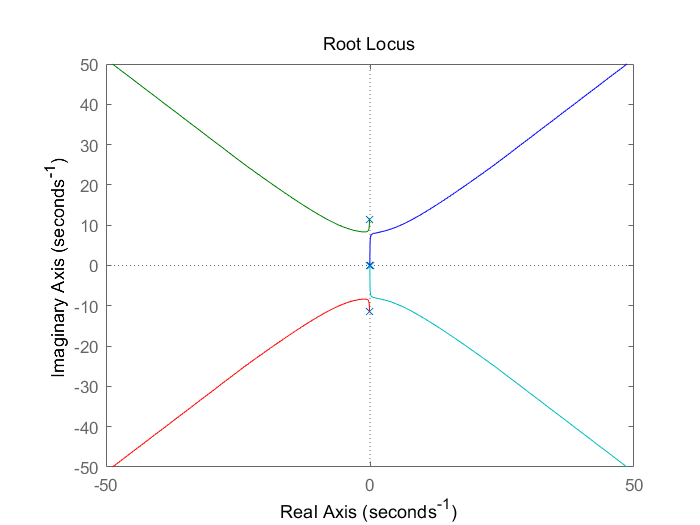

clear all
syms s
k = 6; Jl= 0.5; Jm= 0.05; Bl= 0.01; Bm= 0.01;
a=2;
Kp=0.0018;
% Kp=0.4;%不稳定
Kd=Kp/a;
pl=Jl*s^2+Bl*s+k;
pm=Jm*s^2+Bm*s+k;

PD_simulink=Kp+Kd*s;
pl_simulink=k/pl;
pm_simulink=1/pm;

pms=Jm*s^2+Bm*s+k;
pls=Jl*s^2+Bl*s+k;
gp1=1/pms;
gp2=k/pls;
gp3=gp1*gp2/(1-k*gp1*gp2);

%计算系统传函--未增加PD校正环节，未加反馈
tf_zata_l_un=collect(simplify(gp3));
[I,D]=numden(sym(tf_zata_l_un));
I=eval(I);  %分子
num_un=I;
D=eval(D);  %分母
den_un=sym2poly(D);
sys_un=tf(num_un,den_un);
rlocus(sys_un);

% %计算系统传函--增加PD校正环节，未加反馈
% tf_zata_l_pd=simplify(PD_simulink*(pl_simulink*pm_simulink/(1-pl_simulink*pm_simulink*k)));
% [I,D]=numden(sym(tf_zata_l_pd));
% I=eval(I);  %分子
% num_pd=sym2poly(I);
% D=eval(D);  %分母
% den_pd=sym2poly(D);
% sys_pd=tf(num_pd,den_pd)
% rlocus(sys_pd)

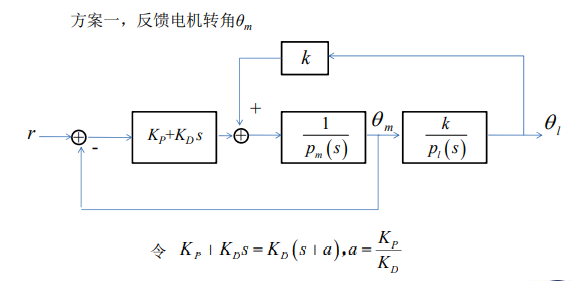

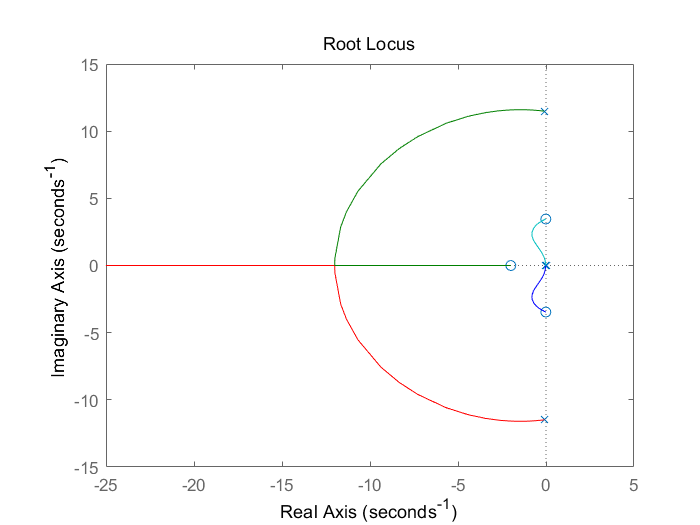

%电机转角zata_m
%计算系统传函--增加PD校正环节,增加反馈
a=2;
Kp1=0.0052; %调节时间较长
Kp=20;%性能好的极点
Kd=Kp/a;
Kd1=Kp1/a;
pl=Jl*s^2+Bl*s+k;
pm=Jm*s^2+Bm*s+k;

G0H=(Kd*(s+a)*pl)/(pl*pm-k^2);%开环传函


PD_simulink=Kp+Kd*s;
PD_simulink1=Kp1+Kd1*s;
pl_simulink=k/pl;
pm_simulink=1/pm;

R_11=(PD_simulink1*pm_simulink);
R_21=R_11/(1+R_11);
R_31=R_21*pl_simulink;
R_41=k*(1/PD_simulink1);
R_51=simplify(R_31/(1-R_31*R_41));

R_1=(PD_simulink*pm_simulink);
R_2=R_1/(1+R_1);
R_3=R_2*pl_simulink;
R_4=k*(1/PD_simulink);
R_5=simplify(R_3/(1-R_3*R_4));


tf_zata_m=simplify(G0H);
[I,D]=numden(sym(tf_zata_m));
I=eval(I);  %分子
num=sym2poly(I);
D=eval(D);  %分母
den=sym2poly(D);
sys_zata_m=tf(num,den);
rlocus(sys_zata_m)

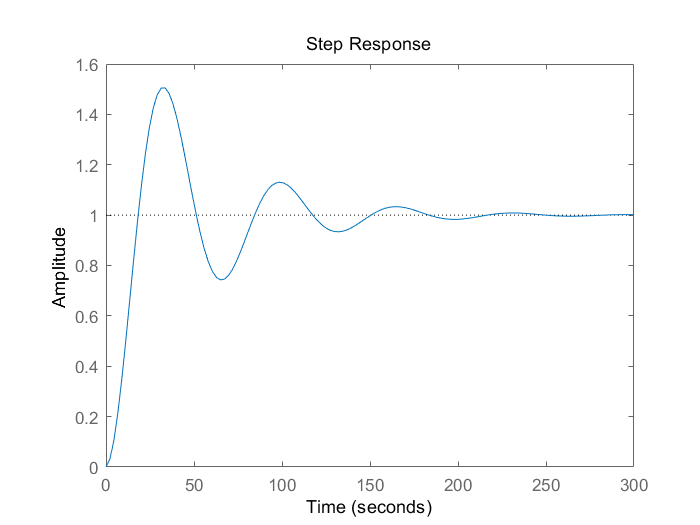

tf_zata_m1=simplify(R_51);
[I1,D1]=numden(sym(tf_zata_m1));
I1=eval(I1);  %分子
num1=sym2poly(I1);
D1=eval(D1);  %分母
den1=sym2poly(D1);
sys_zata_m1=tf(num1,den1);
step(sys_zata_m1)

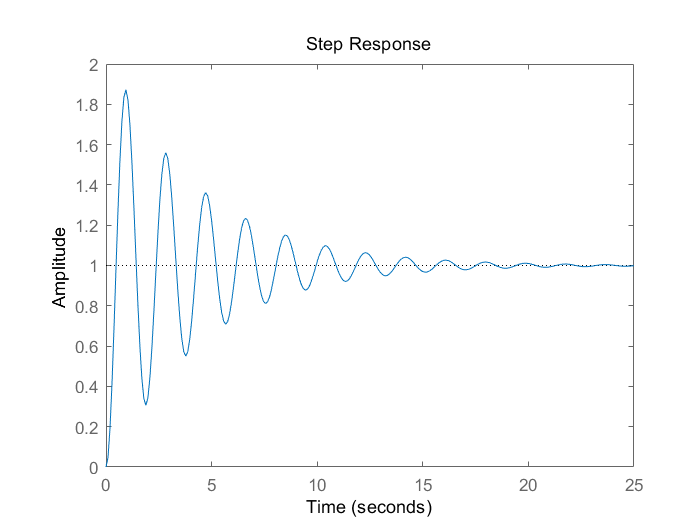

tf_zata_m2=simplify(R_5);
[I2,D2]=numden(sym(tf_zata_m2));
I2=eval(I2);  %分子
num2=sym2poly(I2);
D2=eval(D2);  %分母
den2=sym2poly(D2);
sys_zata_m2=tf(num2,den2);
step(sys_zata_m2)

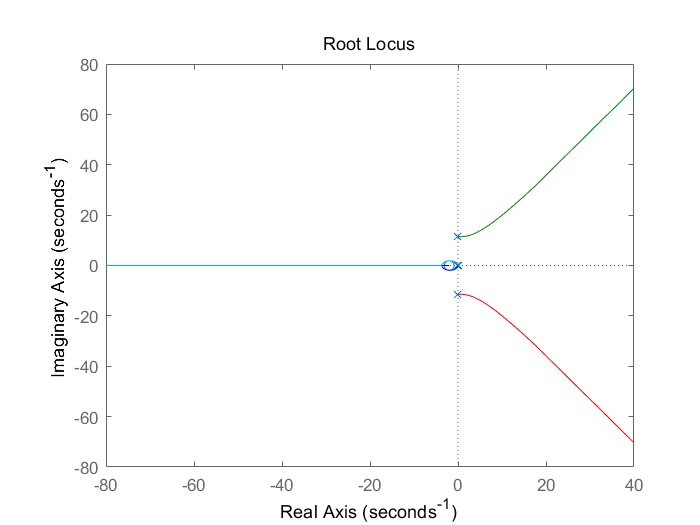


%负载转角zata_l
%计算系统传函--增加PD校正环节,增加反馈

R_1=(pm_simulink*pl_simulink);
R_2=R_1/(1-k*R_1);
% R_3=R_2*(0.0018+0.089*s+7.23*10^(-6)/s);
R_3=R_2*PD_simulink;
R_4=R_3/(1+R_3);

g0h=(Kd*(s+a)*k)/(pl*pm-k^2);%开环传函

pd=0.0018+0.089*s+7.23*10^(-6)/s;
gspd2=pd*gp3/(1+gp3*pd/gp2);

tf_zata_l=simplify(g0h);
[I,D]=numden(sym(tf_zata_l));
I=eval(I);  %分子
num=sym2poly(I);
D=eval(D);  %分母
den=sym2poly(D);
sys_zata_l=tf(num,den);
rlocus(sys_zata_l)

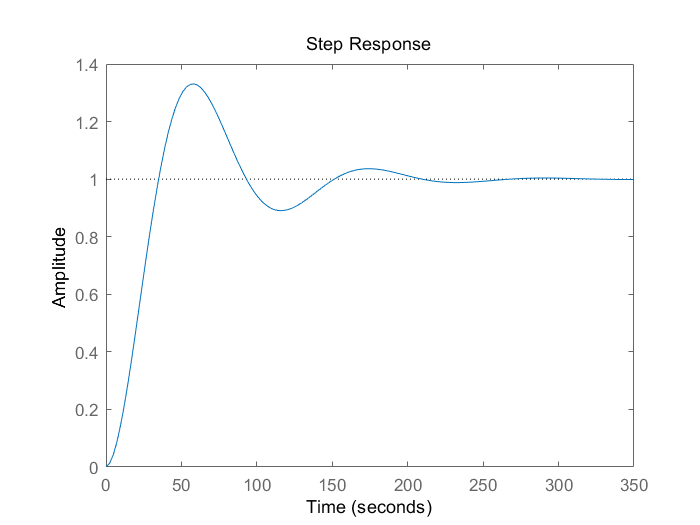

Kp=0.0018;
Kd=Kp/a;
PD_simulink=Kp+Kd*s;
tf_zata_l1=simplify(R_4);
[I2,D2]=numden(sym(tf_zata_l1));
I2=eval(I2);  %分子
num2=sym2poly(I2);
D2=eval(D2);  %分母
den2=sym2poly(D2);
sys_zata_l1=tf(num2,den2);
step(sys_zata_l1)

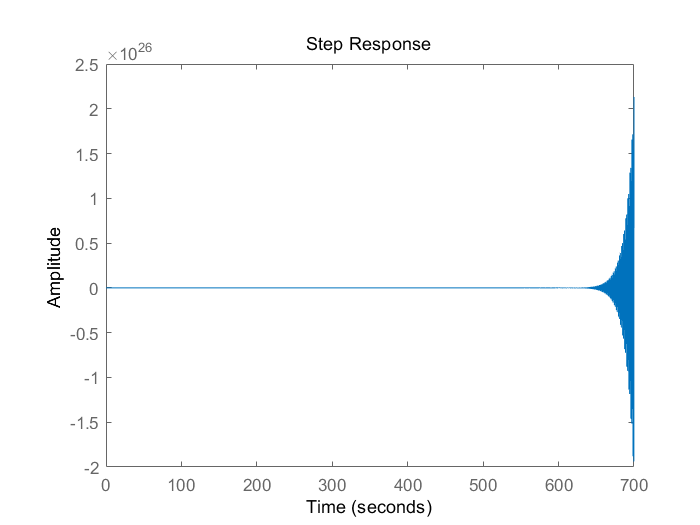

%选择一组不稳定极点
Kp=0.4;
Kd=Kp/a;
PD_simulink=Kp+Kd*s;
R_1=(pm_simulink*pl_simulink);
R_2=R_1/(1-k*R_1);
% R_3=R_2*(0.0018+0.089*s+7.23*10^(-6)/s);
R_3=R_2*PD_simulink;
R_4=R_3/(1+R_3);

tf_zata_l2=simplify(R_4);
[I3,D3]=numden(sym(tf_zata_l2));
I3=eval(I3);  %分子
num3=sym2poly(I3);
D3=eval(D3);  %分母
den3=sym2poly(D3);
sys_zata_l2=tf(num3,den3);
step(sys_zata_l2)

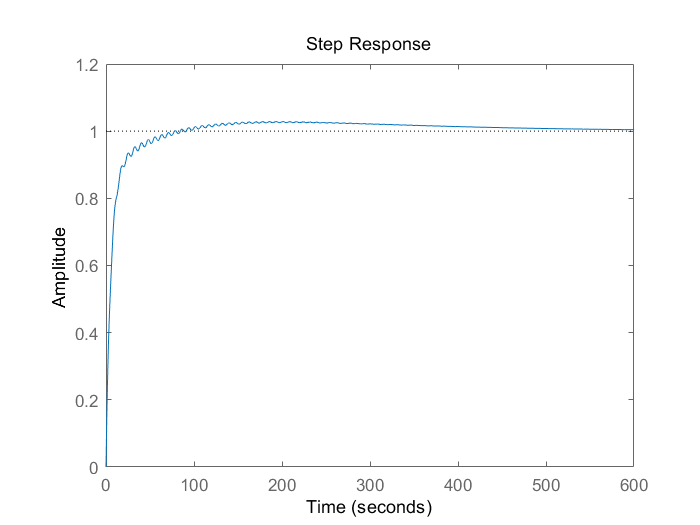

%PID整定
PD_simulink=0.0018+0.089*s+7.23*10^(-6)/s;
R_1=(pm_simulink*pl_simulink);
R_2=R_1/(1-k*R_1);
% R_3=R_2*(0.0018+0.089*s+7.23*10^(-6)/s);
R_3=R_2*PD_simulink;
R_4=R_3/(1+R_3);

tf_zata_l2=simplify(R_4);
[I3,D3]=numden(sym(tf_zata_l2));
I3=eval(I3);  %分子
num3=sym2poly(I3);
D3=eval(D3);  %分母
den3=sym2poly(D3);
sys_zata_l2=tf(num3,den3);
step(sys_zata_l2)

%李雅普诺夫稳定性判定

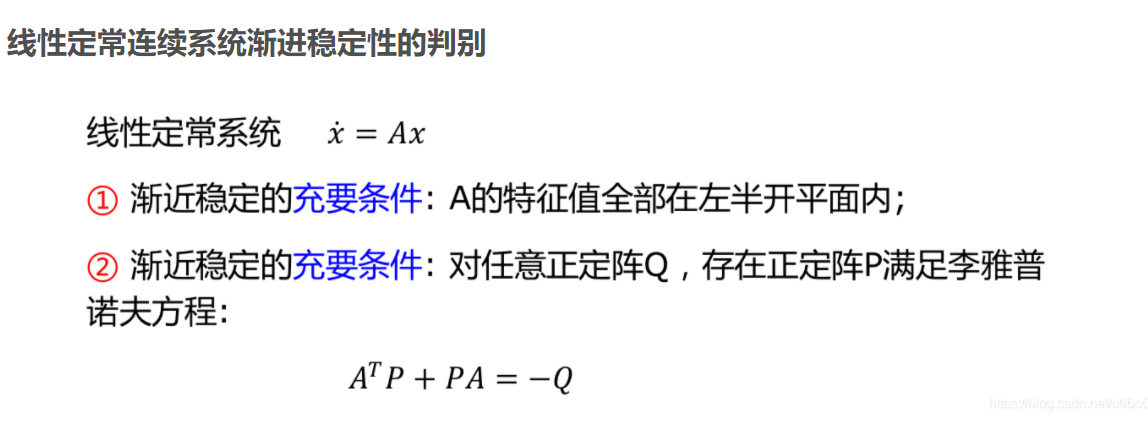

% AX + XA' = -C  
% 这是函数的内部定义式，恰好与理论定义的转置是反着的
P = lyap(A', I) % 一般令Q=I（I指单位阵）

P = 	1.0e+16 *

    0.0031    0.1575    0.0031    0.0157
    0.1575    7.8734    0.1575    0.7873
    0.0031    0.1575    0.0031    0.0157
    0.0157    0.7873    0.0157    0.0787


all(eig(P)>0&imag(eig(P))==0)

ans = logical
   1


%取Q=I时，此时P为正定矩阵，系统稳定
[V,D]=eig(A) % D的对角线上即为特征值

V =    0.0002 + 0.0086i   0.0002 - 0.0086i   0.7066 + 0.0000i   0.7071 + 0.0000i
  -0.0991 + 0.0016i  -0.0991 - 0.0016i  -0.0257 + 0.0000i  -0.0000 + 0.0000i
  -0.0007 - 0.0863i  -0.0007 + 0.0863i   0.7067 + 0.0000i   0.7071 + 0.0000i
   0.9913 + 0.0000i   0.9913 + 0.0000i  -0.0257 + 0.0000i  -0.0000 + 0.0000i


D =   -0.0918 +11.4886i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0918 -11.4886i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0364 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i


%此时A的特征值全部在左半平面，系统稳定

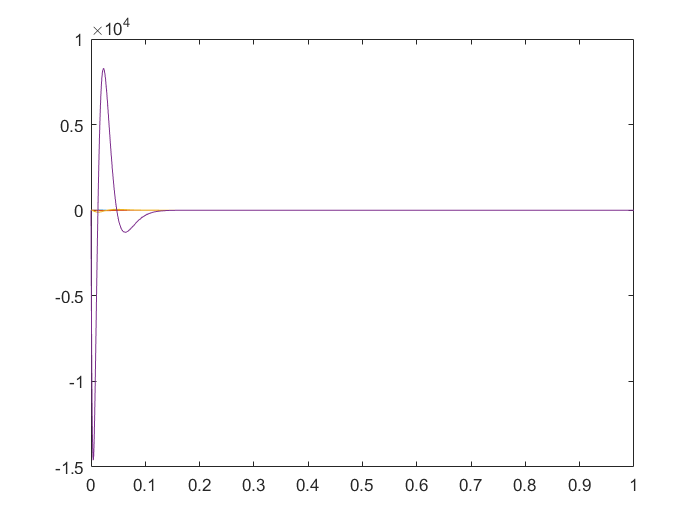

%全状态反馈
Qc=ctrb(A,B); % 求取系统的能控矩阵
rank(Qc);
%能控标准型
p1=[0 0 0 1]*(inv(Qc));
P=[p1;p1*A;p1*(A^2);p1*(A^3)];
A_ba_a=P*A*inv(P);
B_ba_a=P*B;
C_ba_c=C*inv(P);
%状态反馈矩阵
% p1=-0.5;p2=-0.5;p3=-0.5;p4=-0.5;
p1=-100;p2=-100;p3=-100;p4=-100;
% K=place(A,B,[p1,p2,p3,p4])
M=[p1;p2;p3;p4]; %新的极点
K=acker(A,B,M); % Ackermann公式,求解状态反馈阵K,其中，A、B为系统的状态空间模型矩阵，向量P中是期望的闭环极点位置，返回值是增益向量。
k1=K(1);
k2=K(2);
k3=K(3);
k4=K(4);
%利用ode45的数值解判断非零初值能否回到稳定状态
[time_lin,sol_lin]=ode45(@state_feedback_fun,[0 1],[x1 x2 x3 x4]);%
plot(time_lin,sol_lin);

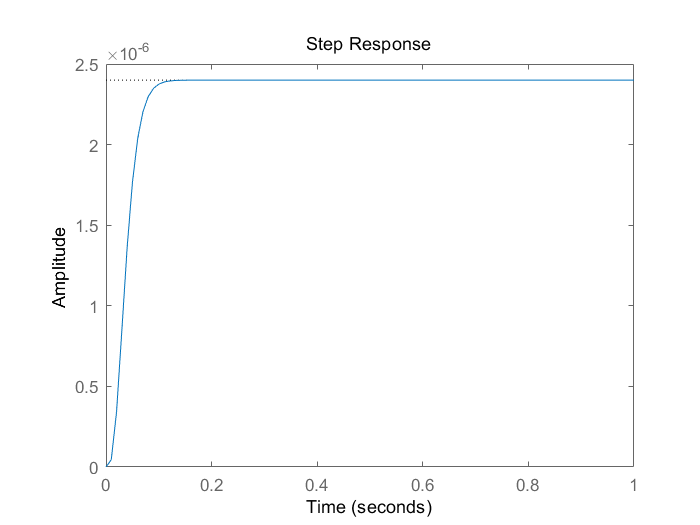


%阶跃输入响应
sys=ss(A-B*K,B,C,D);
[z,p,k]=ss2zp(A-B*K,B,C,D);
sys2=zpk(z,p,k);
t=0:0.01:1;
[num,den]=ss2tf(A-B*K,B,C,D);
sys_use=tf(num,den);
step(sys_use,t)

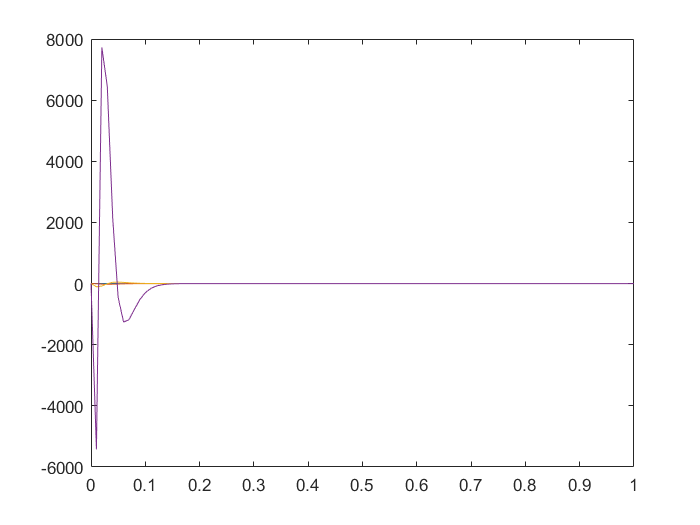

% % [y,t,x]=lsim(sys,u,t,x0);%lsim任意输入u的响应，x0状态初始值，y输出
[y,t,x]=lsim(sys,stepfun(t,0),t,[x1 x2 x3 x4]);%lsim任意输入u的响应，x0状态初始值，y输出
for i=1:4
   plot(t,x(:,i))
   hold on
end
% legend('y','yd','ydd','yddd')
hold off

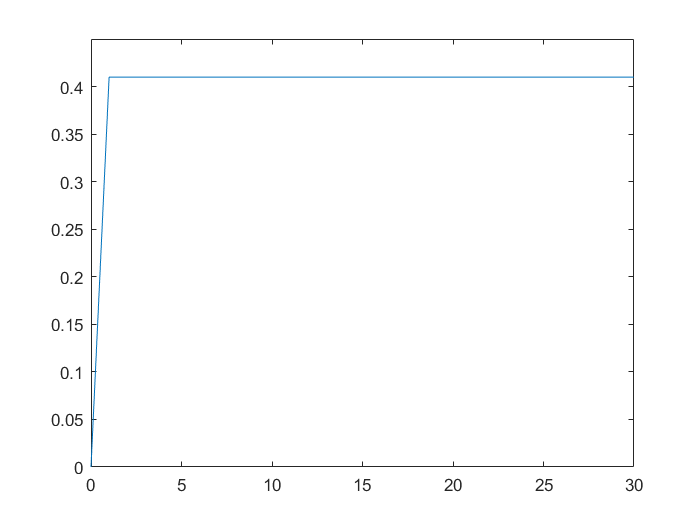

%参考输入
t=0:1:30;
[y,t,x]=lsim(sys,170820*ones(1,31),t);
plot(t, y)

%状态观测器
P1=[-120; -130; - 140; -150];
P2=[-300; -310; -320 ; -330];
% 判断系统是否完全能观
E_obs = obsv(A,C);          % 求解能观性矩阵
E_val = rank(E_obs);         % 根据能控性矩阵是否满秩判断能观性
L1 = (acker(A',C',P1))'  % 利用acker求状态增益矩阵

L1 = 	1.0e+07 *

    0.0001
    0.0109
    0.0807
    2.6050


L2= (acker(A',C',P2))'

L2 = 	1.0e+08 *

    0.0000
    0.0059
    0.1038
    8.1038


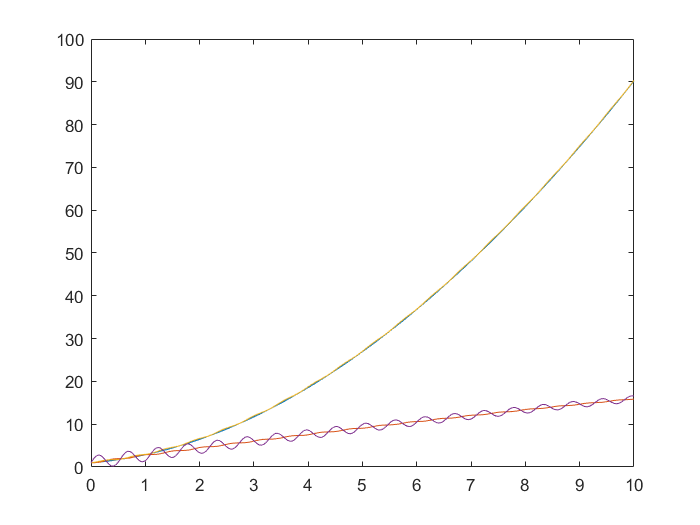

%第一组极点
[time_lin,sol_lin]=ode45(@observer,[0 10],[x1 x2 x3 x4]);%
plot(time_lin,sol_lin);

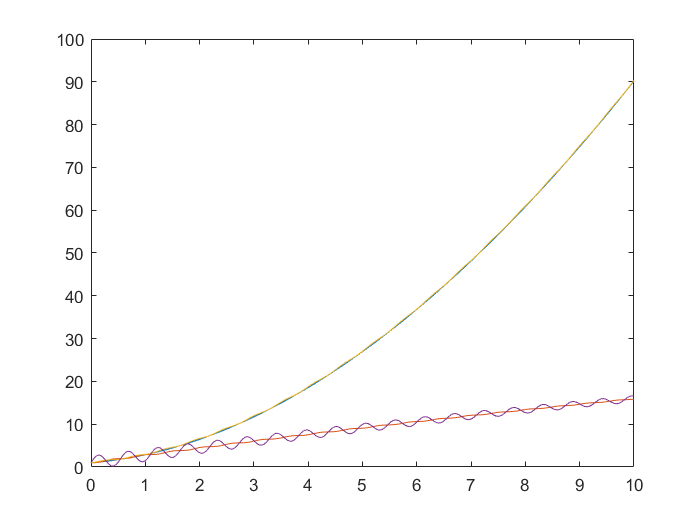

%第二组极点
[time_lin1,sol_lin1]=ode45(@observer1,[0 10],[x1 x2 x3 x4]);
plot(time_lin1,sol_lin1);

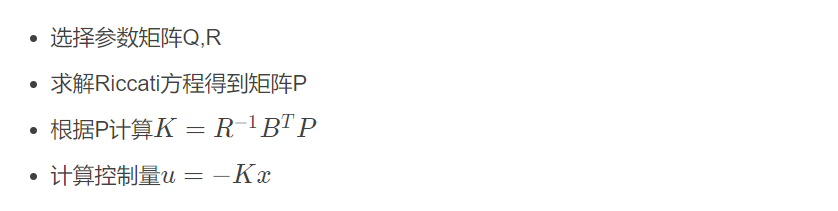

%LPR控制器
Q=[1 0 0 0;0 1 0 0;0 0 1 0;0 0 0 1]; %Q为给定的半正定实对称常数矩阵,Q越大收敛速度越快
R=1;%R为给定的正定实对称常数矩阵，R越大收敛效果越好
% K1为最优反馈增益矩阵；
% S为对应Riccati方程的唯一正定解P（若矩阵A-BK是稳定矩阵，则总有正定解P存在）；
% E为矩阵A-BK的特征值
[K1,S,E] = lqr(A,B,Q,R);
k1_1=K1(1);
k1_2=K1(2);
k1_3=K1(3);
k1_4=K1(4);
sys=ss(A-K1*B,B,C,D);
t=0:0.01:10;
[num,den]=ss2tf(A-B*K1,B,C,D);
sys_use=tf(num,den)


sys_use =
 
                       240
  ---------------------------------------------
  s^4 + 21.67 s^3 + 166.8 s^2 + 467.8 s + 339.4
 
Continuous-time transfer function.



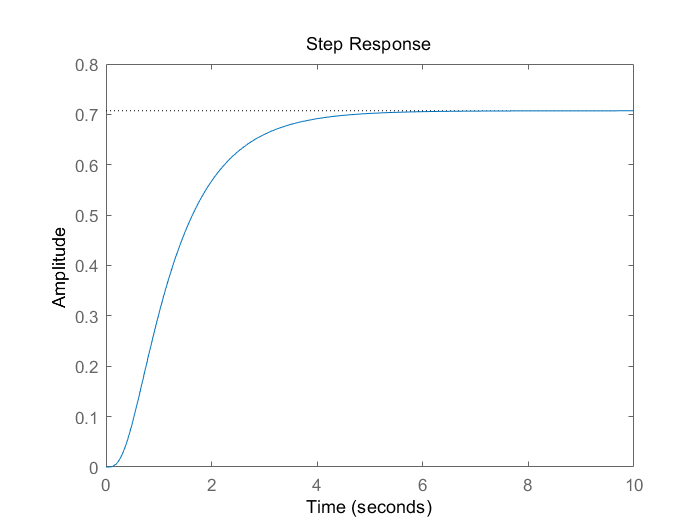

step(sys_use,t)

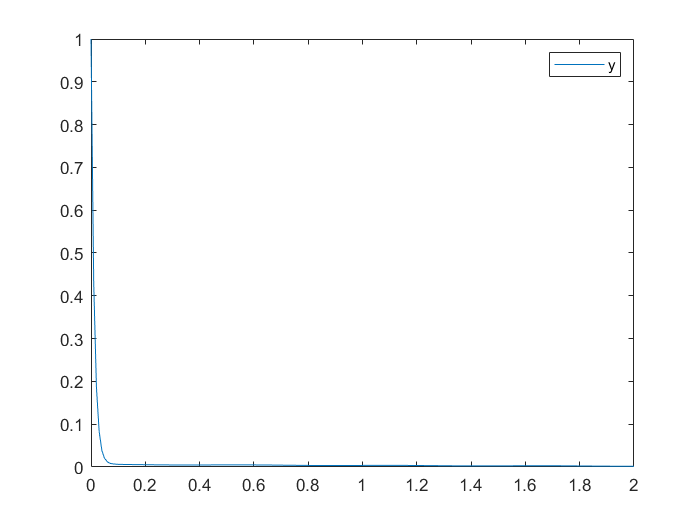

% [y,t,x]=lsim(sys,u,t,x0);%lsim任意输入u的响应，x0状态初始值，y输出
t=0:0.01:2;
u=zeros(size(t));%判断是否会回到平衡点（0,0）stepfun(t,0)
[y,t,x]=lsim(sys,u,t,[x1 x2 x3 x4]);%lsim任意输入u的响应，x0状态初始值，y输出
plot(t,x(:,1))
legend('y')

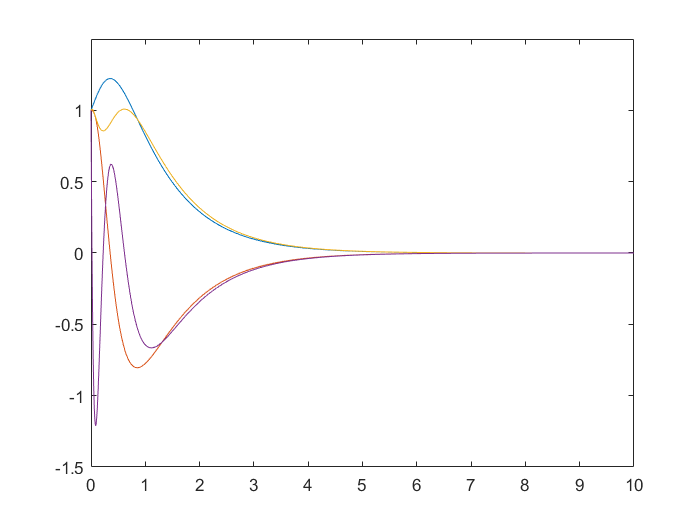

% hold off
%利用ode45的数值解判断非零初值能否回到稳定状态
[time_lin,sol_lin]=ode45(@state_feedback_fun1,[0 10],[x1 x2 x3 x4]);%
plot(time_lin,sol_lin);